#### Connect MATLAB to Gazebo using the ROS Toolbox

Start a ROS node from MATLAB to interact with the Gazebo environment. For more information on interaction with the ROS ecosystem from MATLAB visit [Getting Started with ROS Toolbox](https://www.mathworks.com/help/ros/getting-started-with-ros-toolbox.html).

If you are having trouble with this step, or if you are waiting a long time for the nodes to communicate, try using the commented code in line 4. The IP address to be specified is the wireless network adapter address.

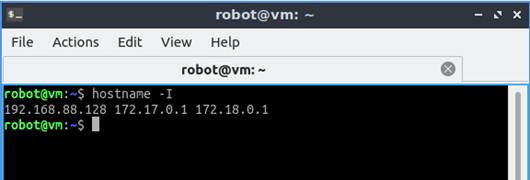

rosIP = "192.168.42.128"; % Change IP address!!    % IP address of ROS enabled machine  
rosshutdown; % shut down existing connection to ROS

Shutting down global node /matlab_global_node_97451 with NodeURI http://192.168.42.1:49979/ and MasterURI http://192.168.42.128:11311.


rosinit(rosIP,11311);

Initializing global node /matlab_global_node_05551 with NodeURI http://192.168.42.1:49986/ and MasterURI http://192.168.42.128:11311.


% rosinit(rosIP,'NodeHost','192.168.68.120') % Try specifying node host IP in case that there are multiple network adapters

## Initialize Robot and Start Simulator

#### Set initial robot configuration

setInitialConfig_franka; % DO NOT MODIFY

#### Unpause GAZEBO physics.

Unpausing the Gazebo simulation is necessary to make sure the environment physics are active.

physicsClient = rossvcclient('gazebo/unpause_physics'); %unpause physics
physicsResp = call(physicsClient,'Timeout',3); %send default message

## Control Gripper Using ROS Action Client

[gripAct,gripGoal] = rosactionclient('/franka_gripper/gripper_action');
gripperCommand = rosmessage(gripAct);

## Control Gripper Position using ROS Action Client

#### Setup ROS message and publisher for Joint Control

jointMess = rosmessage("geometry_msgs/PoseStamped");
jointPub = rospublisher("/cartesian_impedance_example_controller/equilibrium_pose");
pause(2);

## Rutina para objetos estáticos

**Rutina para botella azul**

pause(15)

rx = -pi;
ry = -0.01;
rz = 0;

%Posición de inicio
MoveGripper(-0.38,-0.5,0.2,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)

%Abrir gripper
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(4)

%Posición antes de agarrar botella azul
MoveGripper(-0.07,-0.52,0.2,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



%wait
pause(4)

%Posición para agarrar botella azul
MoveGripper(-0.07,-0.46,0.08,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)

%Tomar botella azul
OpenGripper(2,15,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(4)

%Posición después de agarrar botella azul
MoveGripper(-0.08,-0.5,0.2,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)

%Posición para tirar la botella azul
MoveGripper(-0.38,-0.5,0.2,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(4)

%Soltar botella azul
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

ans = logical
   1



pause(4)

**Rutina botella amarilla**

rx = -pi;
ry = -0.01;
rz = 0;

%Posición inicio
MoveGripper(0.4,0,0.3,rx,ry,rz,jointMess,jointPub)

ans = logical
   1



pause(7)

%Posición para acercarse a la botella amarilla
MoveGripper(0.04,0.53,0.2,rx,ry,rz,jointMess,jointPub)

pause(7)

%Posición antes de orillar la caja
MoveGripper(0.05,0.6,-0.04,rx,ry,rz,jointMess,jointPub)

pause(7)

%Posición para orillar la caja
MoveGripper(0.1,0.6,-0.06,rx,ry,rz,jointMess,jointPub)

pause(6)

%Posición para orillar la caja
MoveGripper(0.1,0.45,-0.06,rx,ry,rz,jointMess,jointPub)

pause(6)

%Posición para acercarse a la botella amarilla
MoveGripper(0.04,0.53,0.05,rx,ry,rz,jointMess,jointPub)

pause(6)

%Abri gripper
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

pause(5)

%Posición para tomar a la botella amarilla
MoveGripper(0.042,0.53,-0.07,rx,ry,rz,jointMess,jointPub)

pause(8)

%Cerrar gripper
OpenGripper(2,20,gripAct,gripGoal,gripperCommand)

pause(6)

%Posición para subir la botella amarilla
MoveGripper(0.04,0.53,0.35,rx,ry,rz,jointMess,jointPub)

pause(5)

%Posición en camino al bote
MoveGripper(0.4,0,0.35,rx,ry,rz,jointMess,jointPub)

pause(5)

%Posición para tirar la botella azul
MoveGripper(-0.33,-0.5,0.2,rx,ry,rz,jointMess,jointPub)

pause(5)

%Abrir gripper
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

pause(5)

**Rutina para botella roja**

rx = -pi;
ry = -0.01;
rz = 0;

%Posición inicio
MoveGripper(0.4,0,0.3,rx,ry,rz,jointMess,jointPub)

pause(4)

%Abrir gripper
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

pause(4)

%Posición para acercarse a la botella roja
MoveGripper(0.4,0.63,0.3,rx,ry,rz,jointMess,jointPub)

pause(4)

rx = -pi;
ry = -0.01;
rz = -pi/2;

%Posición para acercarse a la botella roja
MoveGripper(0.25,0.52,0.3,rx,ry,rz,jointMess,jointPub)

pause(6)

%Posición para empujar a la lata roja
MoveGripper(0.25,0.52,-0.07,rx,ry,rz,jointMess,jointPub)

pause(5)

%Posición para empujar a la lata roja
MoveGripper(0.35,0.52,-0.07,rx,ry,rz,jointMess,jointPub)

pause(4)

%Posición para acercarme a la botella roja
MoveGripper(0.35,0.52,0.03,rx,ry,rz,jointMess,jointPub)

pause(4)

rx = -pi;
ry = -0.01;
rz = 0;

%Posición para acercarme a la botella roja
MoveGripper(0.35,0.63,0.03,rx,ry,rz,jointMess,jointPub)

pause(6)

%Posición para acercarme a la botella roja
MoveGripper(0.4,0.625,-0.02,rx,ry,rz,jointMess,jointPub)

pause(5)

%Abri gripper
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

pause(5)

%Posición para tomar a la botella roja
MoveGripper(0.42,0.625,-0.07,rx,ry,rz,jointMess,jointPub)

pause(5)

%Cerrar gripper
OpenGripper(2,15,gripAct,gripGoal,gripperCommand)

pause(5)

%Posición para tomar a la botella roja
MoveGripper(0.42,0.625,0.3,rx,ry,rz,jointMess,jointPub)

pause(5)

%Posición en camino al bote
MoveGripper(0.4,0,0.3,rx,ry,rz,jointMess,jointPub)

pause(5)

%Posición para tirar la botella azul
MoveGripper(-0.33,-0.5,0.2,rx,ry,rz,jointMess,jointPub)

pause(5)

%Abrir gripper
OpenGripper(4,20,gripAct,gripGoal,gripperCommand)

pause(5)

## **Rutina Cubos única foto**

%Posición inicio
x = 0.626;
y = -0.033;
z = 0.3;
rx = -pi;
ry = -0.01;
rz = 0;

MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)

pause(20)


**Get image **

rgbImgSub = rossubscriber("/camera/rgb/image_raw","sensor_msgs/Image","DataFormat","struct");
curImage = receive(rgbImgSub,3);
pause(1)
rgbImg = rosReadImage(rgbImgSub.LatestMessage); 
rgbDptSub = rossubscriber('/camera/depth/image_raw');
curDepth = receive(rgbDptSub,3);
depthImg = readImage(rgbDptSub.LatestMessage); 
imshowpair(rgbImg,depthImg,"montage")

## **Pre-processing**

Creamos la primera máscara que retira la mesa y las cajas. Hacemos overlay para obtener la imagen sin mesa ni cajas.

imgF = rgbImg(1:450,:,:);
imgD = depthImg(1:450,:);
mask = BW_prueba01(imgF);
%imshow(mask)
justBot = imoverlay(imgF,mask,"k");
%imshow(justBot)

Creamos una segunda máscara a partir de la imagen anterior. En esta máscara usamos la depth camera para eliminar el piso que pudiese aparecer en la foto.

justBotD = imoverlay(imgD,mask,"white");
justBotD = im2gray(justBotD);
%imshow(justBotD)

%Con imbinarize
% mask = imbinarize(justBotD);
% imshow(mask)
% justBot = imoverlay(imgF,mask,"black");
% imshow(justBot)

%Con threshold
mask = justBotD > 230;
%imshow(mask)
justBot = imoverlay(imgF,mask,"black");
%imshow(justBot)

Aplicamos una operación de imclose para cerrar pequeñas areas que podrían quedar.

SE = strel("disk",3);
mask = imclose(mask,SE);

mask = ~bwareafilt(~mask,[1000 3000]);

justBot = imoverlay(imgF,mask,"k");
imshow(mask)
imshow(justBot)

**Get the boundaries from all the items**


stats = regionprops(~mask,"Centroid","BoundingBox")

imshow(justBot)
hold on

for i = 1:size(stats,1)
    rectangle("Position",stats(i).BoundingBox,'EdgeColor','r')
end

plot(320,315, 'r+', 'MarkerSize', 5, 'LineWidth', 2);


hold off

%Gripper se alinea en el pixel [317,315]

**Obtener PointCloud**

DptPoint = rossubscriber('/camera/depth/points');
pointDepth = receive(DptPoint,3);
xyz = readXYZ(pointDepth);
%pcshow(xyz)
xyz=xyz.*[1 1 -1];
pcshow(xyz)

xyz = pointCloud(xyz)
xs = xyz.XLimits
ys = xyz.YLimits

**Ciclo de trabajo**

%Gripper se alinea en el pixel [317,315]
clear distancias

for i = 1:size(stats,1)
    distancias(i) = sqrt((320 - stats(i).BoundingBox(1))^2 + (315-stats(i).BoundingBox(2))^2)
end

d = distancias < 300

xo = xs(1) + (( 320 * (xs(2) - xs(1)))/640)
yo = ys(2) + (( 315 * (ys(1) - ys(2)))/480)

if sum(d) > 0
    for u = 1:size(d,2)
        x = 0.626;
        y = -0.033;
        z = 0.3;
        rx = -pi;
        ry = -0.01;
        rz = 0;

        if d(u) == 1
            x_u = xs(1) + (( stats(u).Centroid(1) * (xs(2) - xs(1)))/640)
            y_u = ys(2) + (( stats(u).Centroid(2) * (ys(1) - ys(2)))/480)

            dx = x_u - xo
            dy = y_u - yo

            x = x + dy;
            y = y - dx;
            z = 0.3;

            %Alineamos a la posición de la tapa
            MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)
            pause(8)

            %Abrir gripper
            OpenGripper(4,20,gripAct,gripGoal,gripperCommand)
            pause(4)

            %Acercamos el gripper a la altura de la tapa
            z = -0.04;
            MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)
            pause(5);

            %Posicionamos el gripper
            z = -0.09;
            MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)
            pause(6);

            %Cerrar gripper
            OpenGripper(1.5,200,gripAct,gripGoal,gripperCommand)
            pause(4)

            %Levantar gripper
            z = 0.3;
            MoveGripper(x,y,z,rx,ry,rz,jointMess,jointPub)
            pause(4);

            %Yendo a la bascula uwu
            MoveGripper(0.6,0.36,0.3,rx,ry,rz,jointMess,jointPub)
            pause(5)

            %Baja poco a la bascula uwu
            MoveGripper(0.6,0.36,0,rx,ry,rz,jointMess,jointPub)
            pause(5)

            %Baja todo
            MoveGripper(0.6,0.36,-0.03,rx,ry,rz,jointMess,jointPub)
            pause(3)

            %Suelta tapa
            OpenGripper(4,15,gripAct,gripGoal,gripperCommand)
            pause(4)

            %Subimos gripper
            MoveGripper(0.6,0.36,0.03,rx,ry,rz,jointMess,jointPub)
            pause(4)

            %Posicionamos gripper de nuevo
            MoveGripper(0.6,0.36,-0.03,rx,ry,rz,jointMess,jointPub)
            pause(4)

            %Cerramos gripper
            OpenGripper(1.5,100,gripAct,gripGoal,gripperCommand)
            pause(4)

            %Subimos tapa again
            MoveGripper(0.6,0.36,0.3,rx,ry,rz,jointMess,jointPub)
            pause(4)

            %Posición para tirar en el bote verde
            MoveGripper(-0.33,0.5,0.3,rx,ry,rz,jointMess,jointPub)
            pause(4)

            %Abrir gripper
            OpenGripper(4,15,gripAct,gripGoal,gripperCommand)
            pause(4)

            %Subimos tapa again
            MoveGripper(0.6,0.36,0.3,rx,ry,rz,jointMess,jointPub)
            pause(4)
        end
    end
end

function [done] = MoveGripper(x,y,z,rx,ry,rz,message,publisher)
gripperX = x;
gripperY = y;
gripperZ = z;

%gripperTranslation = [gripperX gripperY gripperZ];
gripperRotationX = rx; % radians
gripperRotationY = ry; % radians
gripperRotationZ = rz; % radians

message.Pose.Position.X = gripperX;
message.Pose.Position.Y = gripperY;
message.Pose.Position.Z = gripperZ;
quat = angle2quat(gripperRotationX, gripperRotationY, gripperRotationZ, "XYZ");
message.Pose.Orientation.W = quat(1);
message.Pose.Orientation.X = quat(2);
message.Pose.Orientation.Y = quat(3);
message.Pose.Orientation.Z = quat(4);
send(publisher,message);

done = true;
end

function[done] = OpenGripper(pos,force,act,goal,comando)
comando.Command.Position = pos; %0 is fully closed, 4 is fully open
comando.Command.MaxEffort = force; %N
comando.Command.Position = comando.Command.Position / 100;
goal.Command = comando.Command;
% waitForServer(act); % Can use this function if concerned with missed
% goals but generally it should work correctly.
sendGoal(act,goal)

done = true;
end
